# Analyis of theoretical and simulation results

Parameters

Adding matlab path to: D:\code\NN_molecular_communications\Section_IV_BioComputing\COMSOL_Single_Pipes
L_1=20000 um
L_1=211.98 um
Q_inlet_CNN=5 uL/min
height_pipe=36 um
c_Tartrazine_exp=0.08455 mol/L


c_max = 1

c_inlet=0.001 mol/L


mu = 9.9792e-04

D_coeff=4.9e-10 m^2/s



%Loading simulation results generated by the file COMSOL_Single_Pipe.mph
% Specify the CSV file
csvFileName = 'c_Pipe_1.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
Table_c_Pipe_1=readtable(csvFileName,opts);
t_COMSOL=(Table_c_Pipe_1.Var1);
c_COMSOL_Pipe_1=(Table_c_Pipe_1.Var2);

t=0:time_delta:time_simul;


#### Pulse response

**Description:** Regarding the theoretical calculation we follow the Taylor's model, see [1, Sec. 4.5]. Whenever the Péclet number fulfill the condition in the above Eq. (1), the particles difussion is homogeneous along the $x$-axis and can be evaluated with the non-convection condition, i.e., free difussion in moved coordinate system. For the free difussion scenario, we regard to the case where there the diffusing substance concentrated initially on the negative side of $x'$, where $x'$ refers to the moving coordinates. The moving coordinates is along the $x$ axis of the unmoved coordinates and moves at the average speed of the velocity profile. Considering the initial conditions [3, Sec. 2.2.3 pp. 13]

$C=C_0$, $x'<0$, $C=0$, $x'>0$, $t=0$, (7)

the solution to the diffusion equation yields [3, Eq. (2.14)]

$C(x',t)=\frac{1}{2}C_0\, \mathrm{erfc}\frac{x'}{2\sqrt{Dt}}$.             (8)

Then, within the moved coordinate system $x'=x-v_0t$ and $D=D_\mathrm{eff}$, yielding

$C(x,t)=\frac{1}{2}C_0\, \text{erfc}\left(\frac{x-v_\text{char}t}{2\sqrt{D_\text{eff}\,t}}\right)$,          (9)

where [1, Eq. (4.54) pp. 77]

$D_\text{eff}=D_\text{coeff}\left(1+\frac{1}{200}\text{Pe}^2\right)$,        (10)

is the effective diffusion coefficient, and $v_\text{char}$ is the characteristic speed, here evalueated as the average speed within the microfluidic pipe as [1, below Eq. (3.40) pag. 53]

$v_\text{char}=\frac{Q}{w_1\times \text{height pipe}}$, (11)

and $\text{Pe}$ is the Peclet number evaluated as [3, Eq. below 11]

$\text{Pe}=\frac{v_\text{char}\times \text{height pipe}}{D_\text{coeff}}$ (12)

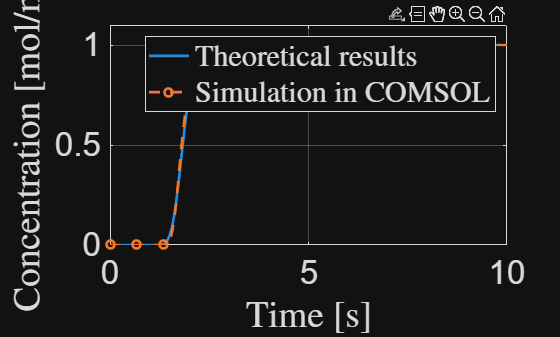


%Mean velocity
%Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
v_char=Q/(w_1*height_pipe);

%Peclet number, see [3, Eq. below 11]
Pe=v_char*height_pipe/D_coeff;

%Evaluating the Effective Diffusion coefficient
%Circular channel: [1, Eq.(4.54) pp.77]
%D_eff=r_vec(i_w)^2*v_char^2/48/D_coeff;
%Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
%Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
D_eff=D_coeff*(1+1/200*Pe^2);

c_Pipe_1=c_Tartrazine./2.*erfc((L_1-v_char*t)./(2*sqrt(D_eff*t)));

figure;
plot(t,c_Pipe_1,'LineWidth',2); grid on; hold on;
plot(t_COMSOL,c_COMSOL_Pipe_1,'o--','LineWidth',2,'MarkerIndices',1:ceil(length(c_COMSOL_Pipe_1)/15):length(c_COMSOL_Pipe_1)); grid on;
xlabel('Time [s]','Interpreter','latex');
ylabel('Concentration [mol/m$^3$]','Interpreter','latex');
set(gca,'FontSize',fontsize);
axis([0 t(end) 0 1.1*max(c_Pipe_1)]);
legend({'Theoretical results','Simulation in COMSOL'},"Interpreter","latex")

#### Impulse response

**Description:** This block evaluates the channel impulse response $h(t)$ for the turning channel. The $h(t)$ sequence is evaluated using the above formulation for the observed concentration of molecules. The above formulation is the step response of the channel when $C_0=1$, as such, the channel impulse response can be evaluated as [4, Eq. (7b), pp. 78]

$h(t)=\frac{\partial}{\partial t}C(x,t)\bigg|_{C_0=1}$,  (13)

where $C(x,t)$ is given as in Eq. (11) above.

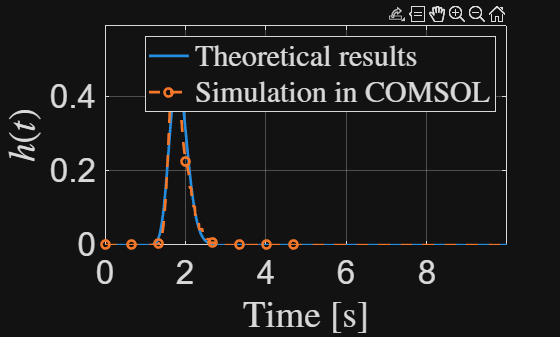

h_Pipe_1=diff(c_Pipe_1)/time_sampling;
h_COMSOL_Pipe_1=diff(c_COMSOL_Pipe_1)/time_sampling;

figure;
plot(t(1:end-1),h_Pipe_1,'LineWidth',2); grid on; hold on;
plot(t_COMSOL(1:end-1),h_COMSOL_Pipe_1,'o--','LineWidth',2,'MarkerIndices',1:ceil(length(h_COMSOL_Pipe_1)/15):length(c_COMSOL_Pipe_1)); grid on;
xlabel('Time [s]','Interpreter','latex');
ylabel ('$h(t)$','Interpreter','latex');
set(gca,'FontSize',fontsize);
legend({'Theoretical results','Simulation in COMSOL'},"Interpreter","latex");
axis([0 t(end-1) 0 1.1*max(max(h_Pipe_1),max(h_COMSOL_Pipe_1))]);

#### Analyzing the biffurcation geometry

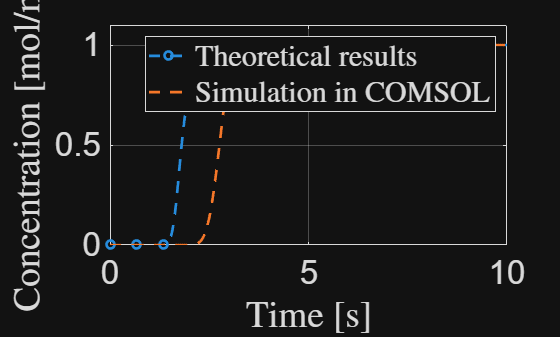

%Loading simulation results generated by the file COMSOL_Single_Pipe.mph
% Specify the CSV file
csvFileName = 'c_Pipe_1_Biff.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
Table_c_Pipe_1=readtable(csvFileName,opts);
t_COMSOL_Biff=(Table_c_Pipe_1.Var1);
c_COMSOL_Pipe_1=(Table_c_Pipe_1.Var2);
c_COMSOL_Pipe_1_Biff=(Table_c_Pipe_1.Var3);
c_COMSOL_Pipe_1_Biff_2=(Table_c_Pipe_1.Var4);

%Impulse response
h_COMSOL_Pipe_1=diff(c_COMSOL_Pipe_1)/time_sampling;
h_COMSOL_Pipe_1_Biff=diff(c_COMSOL_Pipe_1_Biff)/time_sampling;

t=0:time_delta:time_simul;

figure;
% plot(t,c_Pipe_1,'LineWidth',2); grid on; hold on;
plot(t_COMSOL,c_COMSOL_Pipe_1,'o--','LineWidth',2,'MarkerIndices',1:ceil(length(c_COMSOL_Pipe_1)/15):length(c_COMSOL_Pipe_1)); grid on; hold on;
plot(t_COMSOL,c_COMSOL_Pipe_1_Biff,'--','LineWidth',2,'MarkerIndices',1:ceil(length(c_COMSOL_Pipe_1)/15):length(c_COMSOL_Pipe_1)); grid on;

xlabel('Time [s]','Interpreter','latex');
ylabel('Concentration [mol/m$^3$]','Interpreter','latex');
set(gca,'FontSize',fontsize);
axis([0 t(end) 0 1.1*max(c_Pipe_1)]);
legend({'Theoretical results','Simulation in COMSOL'},"Interpreter","latex")

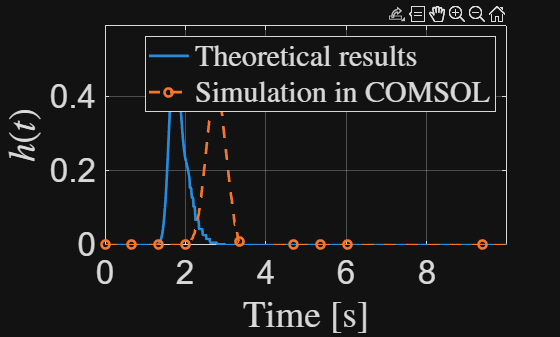



figure;
plot(t(1:end-1),h_COMSOL_Pipe_1,'LineWidth',2); grid on; hold on;
plot(t_COMSOL(1:end-1),h_COMSOL_Pipe_1_Biff,'o--','LineWidth',2,'MarkerIndices',1:ceil(length(h_COMSOL_Pipe_1_Biff)/15):length(c_COMSOL_Pipe_1)); grid on;
xlabel('Time [s]','Interpreter','latex');
ylabel ('$h(t)$','Interpreter','latex');
set(gca,'FontSize',fontsize);
legend({'Theoretical results','Simulation in COMSOL'},"Interpreter","latex");
axis([0 t(end-1) 0 1.1*max(max(h_Pipe_1),max(h_COMSOL_Pipe_1))]);

### References

[1] H. Bruus, Theoretical Microfluidics. 2008. doi: 10.1093/oso/9780199235087.001.0001.  

[2] Howard C. Berg. 1993. Random Walks in Biology. Princeton University Press.

[3] M. L. Parks and L. A. Romero, "Taylor–Aris dispersion in high aspect ratio columns of nearly rectangular cross section," Mathematical and Computer Modelling, vol. 46, no. 5, pp. 699–717, Sep. 2007, doi: 10.1016/j.mcm.2006.11.029. 

[4] Murat paper